Punto 2a

Nx = 2^10;
Ny = 2^10;

% Unidades
nm = 1E-9;
um = 1E-6;
mm = 1E-3;

% Cambio
dx =0.5*um;
dy =0.5*um;

waveLength = 650*nm;

% Condiciones de la rendija
m = 1;
L = 50*dx;

% Distancia de propagación
n = 1;
z = n*((L^2)/waveLength);

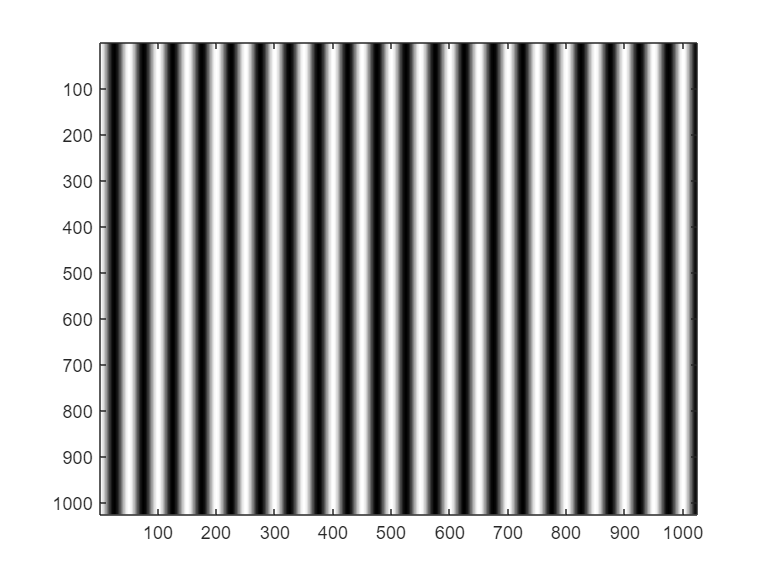

transmitancia = rejilla(Nx,Ny,dx,dy,m,L);
imagesc(transmitancia)
colormap('gray')

tic
transmitanciaProp = transformadaFresnel(transmitancia,dx,dy,z,waveLength,dft=false,zoom = true);
toc

Elapsed time is 0.095889 seconds.


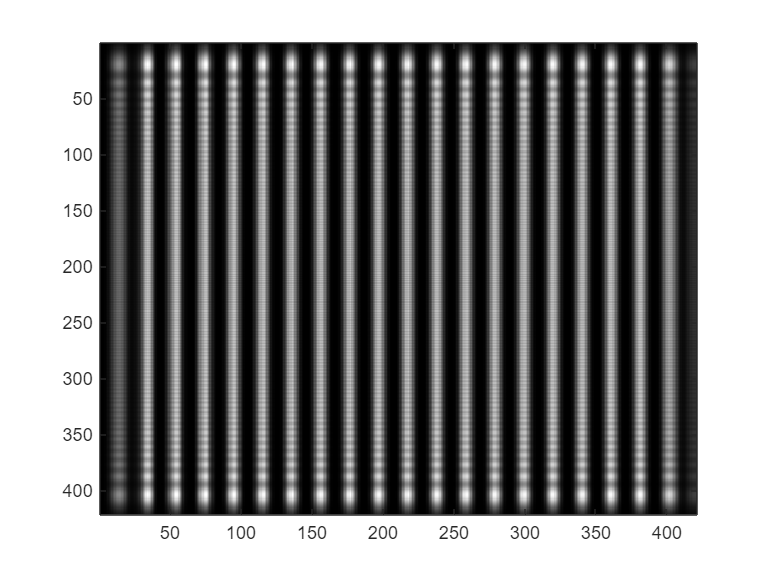

intensidad = abs(transmitanciaProp).^2;
imagesc(intensidad)

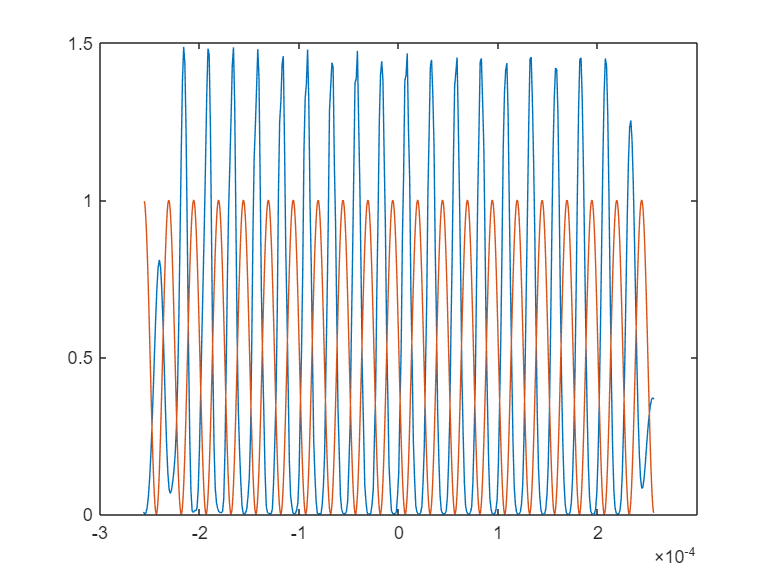

% Perfil de intensidad a lo largo del eje x de la propagada
[hI, wI] = size(intensidad);
Ipropagada = intensidad(round(hI/2),1:end)';
x = 1-round(hI/2):round(hI/2)-1;
x = x*(waveLength*z/(Nx*dx));

% Perfil de intensidad a lo largo del eje x de la rejilla de difraccion
I = transmitancia(round(Ny/2),1:end)';
x0 = 1-Ny/2:Ny/2;
x0 = x0*dx;

% Comparación de las intensidades 
plot(x,Ipropagada*10^37)
hold on
plot(x0,I)
xlim([-3E-4 3E-4])
hold off